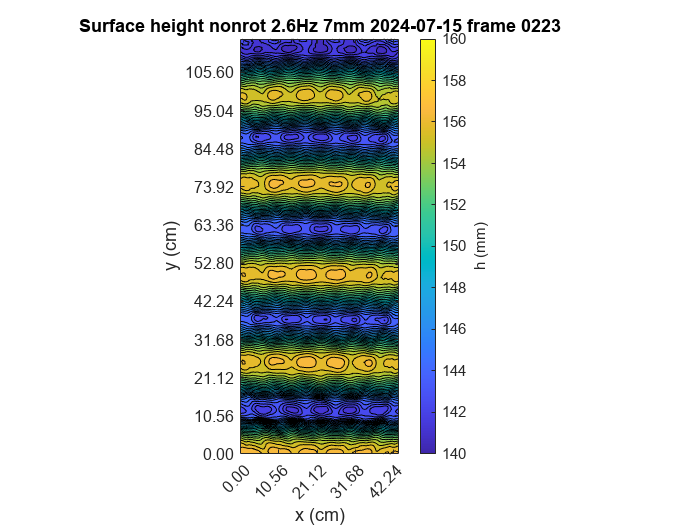

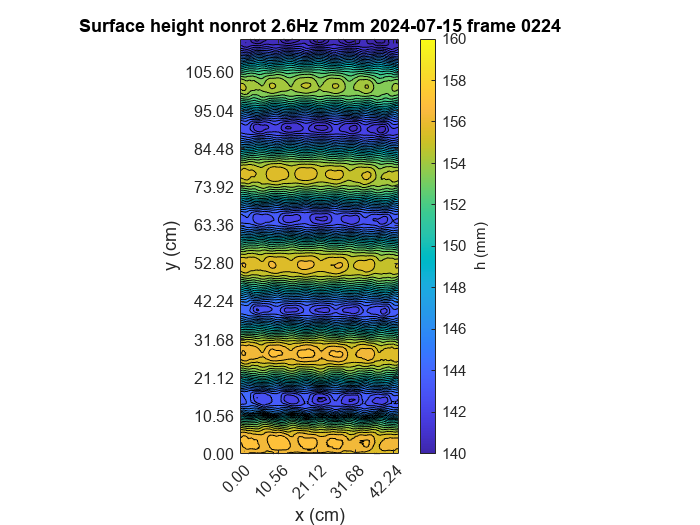

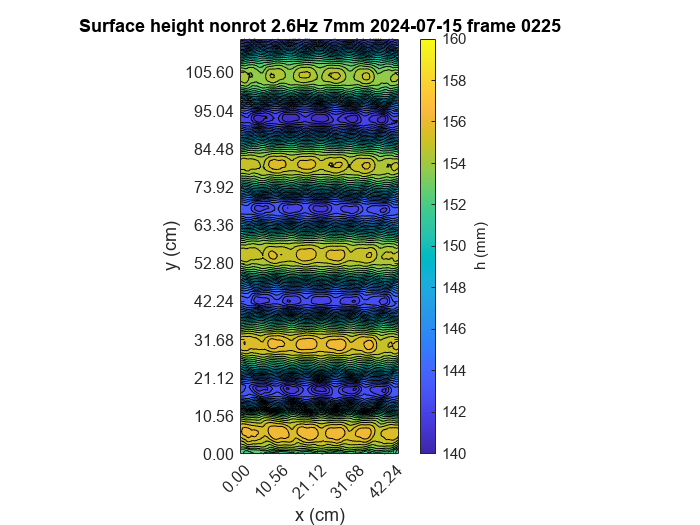

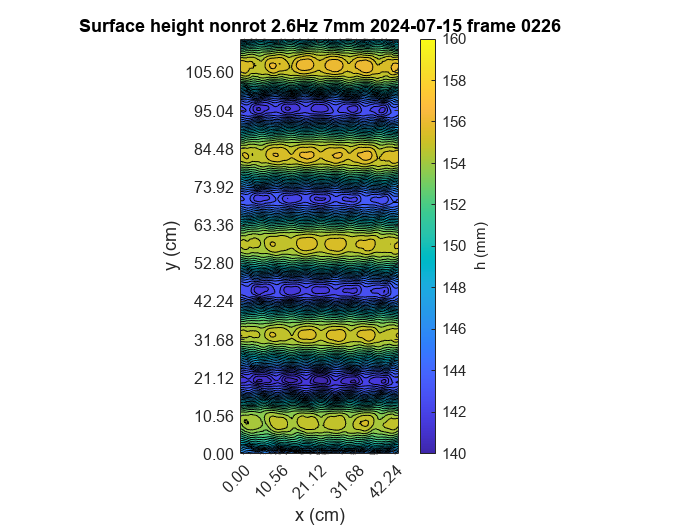

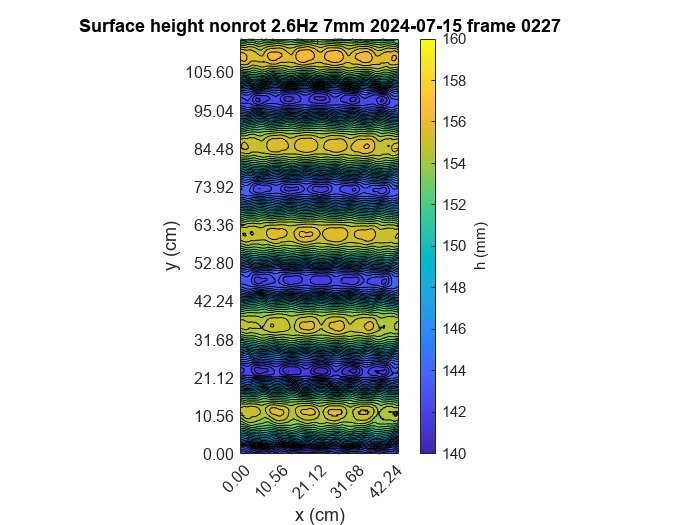

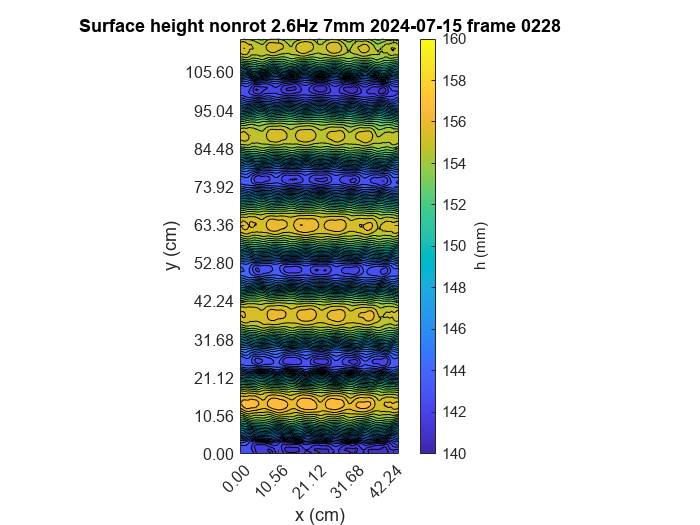

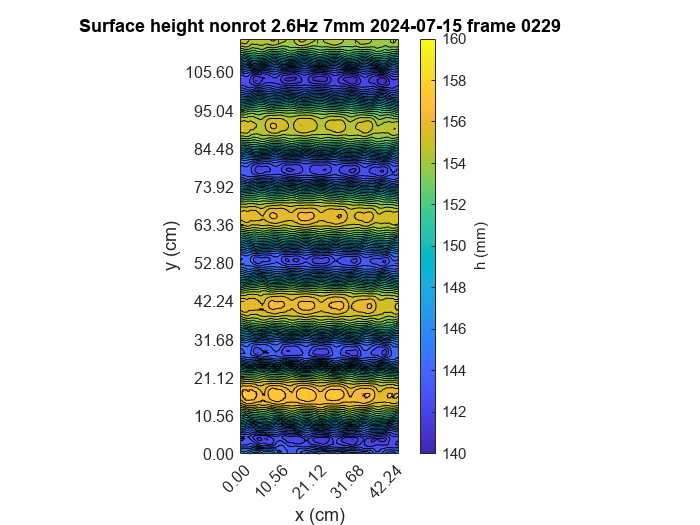

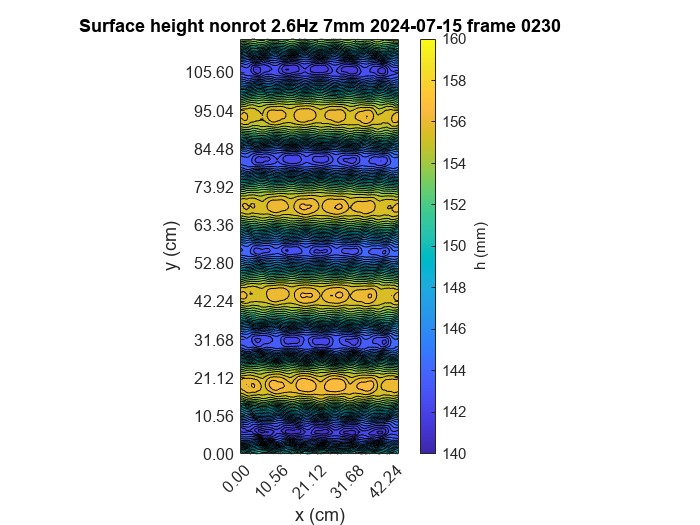

clear 
close all
clc

% Define the base directory for input and output files
input_dir = 'D:\Matlab\Matlab input\20240715_full_plate\20240715_nonrot_2.6Hz_7mm_full_plate_separate_frames\Results\';
output_dir = 'D:\Matlab\Matlab output\20240715_full_plate_results\20240715_nonrot_2.6Hz_7mm_full_plate\';

% Define the base file name and extension
base_file_name = '20240715_nonrot_2.6Hz_7mm_full_plate_frame_';
file_extension = 'A_vel_new.dat';

% Define the range of frames to process
start_frame = 220;
end_frame = 221;

% Loop over the frames
for frame_num = start_frame:end_frame
    % Construct the file name
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);
    
    % Load the data
    dr = loadvec(input_file);

    % Copy dr to dr_new & delete rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % surface-pattern distance in mm
    h = surfheight(dr_new, h_0);

    % Plot the surface height & save figure
    contourf(h.w, 25)
    axis equal
    ax = gca;
    numbers_long_axis = (dr_new.x - 63.3601) ./ 10;     % 47.52
    numbers_short_axis = (dr_new.y + 594.001) ./ 10;

    % Determine the positions of the ticks you want to display (e.g., every 10th label)
    x_tick_positions = 1:40:length(numbers_short_axis);
    y_tick_positions = 1:40:length(numbers_long_axis);

    % Set the ticks at these positions
    ax.XTick = x_tick_positions;
    ax.YTick = y_tick_positions;

    % Set the labels at these positions and format them to 2 decimal places
    ax.XTickLabel = arrayfun(@(x) sprintf('%.2f', x), numbers_short_axis(x_tick_positions), 'UniformOutput', false);
    ax.YTickLabel = arrayfun(@(y) sprintf('%.2f', y), numbers_long_axis(y_tick_positions), 'UniformOutput', false);

    % Set the title and labels
    title(sprintf('Surface height nonrot 2.6Hz 7mm 2024-07-15 frame %s', frame_str));
    col = colorbar;
    xlabel('x (cm)');
    ylabel('y (cm)');
    ylabel(col, 'h (mm)');
    caxis([140, 160]);

    % Save the figure
    output_file = fullfile(output_dir, sprintf('20240715_nonrot_2.6Hz_7mm_full_plate_surface_height_%s.png', frame_str));
    %exportgraphics(gcf, output_file);

    % Close the figure to avoid memory issues
    %close all;
end

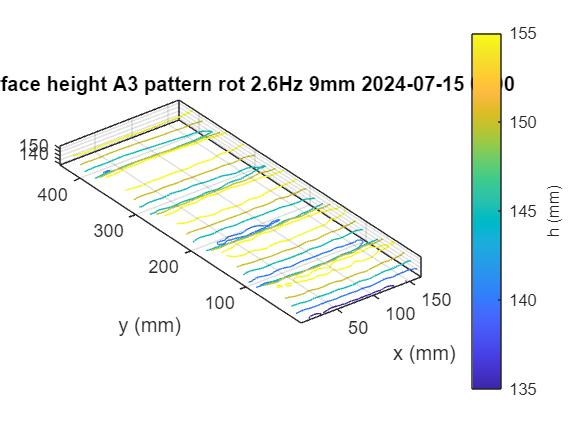

dr = loadvec('D:\Matlab\Matlab input\20240715_full_plate\20240715_rot_2.6Hz_9mm_full_plate_separate_frames\Results\20240715_rot_2.6Hz_9mm_full_plate_frame_0200A_vel_new.dat');

dr_new=dr;
% Delete zeros for x comp

dr_new.vx(:,all(dr_new.vx == 0,1))=[];
dr_new.vx(all(dr_new.vx == 0,2),:)=[];

dr_new.vy(:,all(dr_new.vy == 0,1))=[];
dr_new.vy(all(dr_new.vy == 0,2),:)=[];

% Compute the surface height

%h_0 = 13/0.15; % 1 pixel is 0.15 mm % 11 mm % surface-pattern distance in mm
h_0 = 150; % 150 surface-pattern distance in mm
h = surfheight(dr_new,h_0);
% Plot the surface height & save figure

%surf(h.w)
%showf(h.w)
%contourf(h.w, 25);
contour3(h.w);
axis equal
ax = gca;

title('Surface height A3 pattern rot 2.6Hz 9mm 2024-07-15 0200')
col = colorbar;
xlabel('x (mm)');
ylabel('y (mm)');
ylabel(col,'h (mm)');

%caxis([85, 95]);
%w=h.w
%exportgraphics(gcf,'C:\Users\20182270\OneDrive - TU Eindhoven\Documents\0 Graduation project\Matlab\Output\20240618_new_A3_results\20240618_rot_2Hz_5mm_new_A3_frame_surface_height_0160.png')


% to change axes labels
% % Manually format the labels to have a consistent exponent
% x_tick_labels = numbers_short_axis(x_tick_positions) / 1e1;
% y_tick_labels = numbers_long_axis(y_tick_positions) / 1e1;

% ax.XTickLabel = arrayfun(@(x) sprintf('%.2f\\times10^1', x), x_tick_labels, 'UniformOutput', false);
% ax.YTickLabel = arrayfun(@(y) sprintf('%.2f\\times10^1', y), y_tick_labels, 'UniformOutput', false);
% 

% % Set the labels at these positions
% ax.XTickLabel = numbers_short_axis(x_tick_positions);
% ax.YTickLabel = numbers_long_axis(y_tick_positions);
% 
% % Set the tick format to scientific notation
% xtickformat('%0.1e');
% ytickformat('%0.1e');
